Asignment 2

Slide 2: Load and Describe data

% read xls from sheet monthly
%data = readtable('data/MSPNHSUS.xlsx', Sheet="Monthly");
%cpi_data = readtable('data/CPIAUCSL.xlsx', Sheet="Monthly");

data = readtable('quaterly/MSPUS.xlsx', Sheet='Quarterly');
cpi_data = readtable('quaterly/CPALTT01USQ657N.xlsx', Sheet='Quarterly');
% filter cpi data to start from 01-Jan-1963
cpi_data = cpi_data(cpi_data.observation_date >= datetime('01-Jan-1963'), :);
cpi = cpi_data.CPALTT01USQ657N

cpi =     0.1096
    0.3286
    0.5459
    0.4343
    0.2162
    0.1079
    0.4310
    0.3219
    0.2139
    0.7471
    0.4237
    0.4219
    0.7353
    1.1470
    0.9278


% filter price data to 01-Jan-2024
data = data(data.observation_date <= datetime('01-Jan-2024'), :);
% change column name
data.Properties.VariableNames{'MSPUS'} = 'price';

% Define a description fn
head(data)

    observation_date    price
    ________________    _____

      01-Jan-1963       17800
      01-Apr-1963       18000
      01-Jul-1963       17900
      01-Oct-1963       18500
      01-Jan-1964       18500
      01-Apr-1964       18900
      01-Jul-1964       18900
      01-Oct-1964       19400



% describe data
summary(data);


data: 245×2 table

Variables:

    observation_date: datetime
    price: double

Statistics for applicable variables:

                        NumMissing          Min              Median               Max                    Mean                    Std       

    observation_date        0           01-Jan-1963        01-Jul-1993        01-Jan-2024        01-Jul-1993 11:10:02        155310:36:40  
    price                   0                 17800             127000             442600                  1.5293e+05          1.1299e+05  



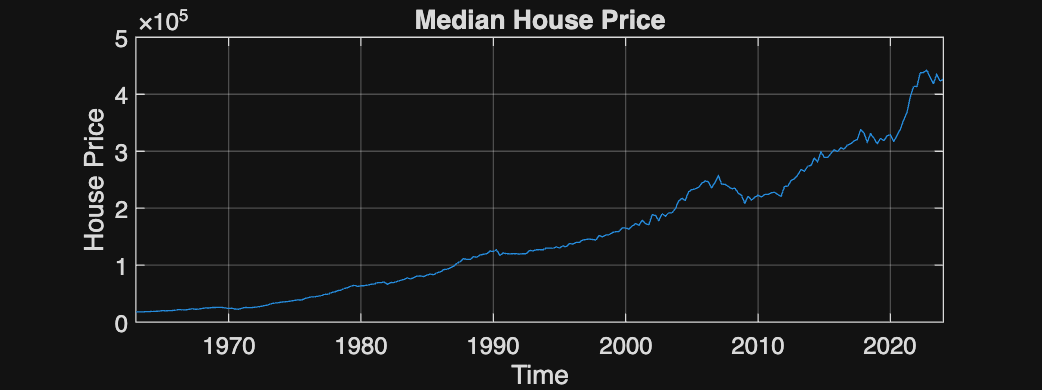

figure;

plot(data.observation_date, data.price)
xlabel('Time');
ylabel('House Price');
title('Median House Price');
grid on;


set(gcf, 'Position', [100, 100, 1600, 600]);

Compute the real price by deflating the price.

real_price = data.price ./ cpi

real_price = 1.0e+07 *

    0.0162
    0.0055
    0.0033
    0.0043
    0.0086
    0.0175
    0.0044
    0.0060
    0.0094
    0.0027
    0.0048
    0.0048
    0.0029
    0.0019
    0.0023


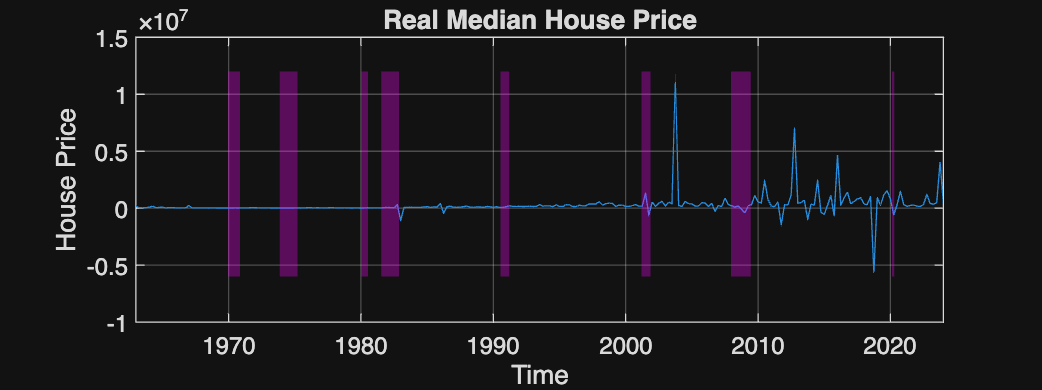

figure;
plot(data.observation_date, real_price);
xlabel('Time');
ylabel('House Price');
title('Real Median House Price');
% plot lines on the major recessions

hBands = recessionplot;
set(hBands,'FaceColor',"magenta",'FaceAlpha',0.3);

grid on;
set(gcf, 'Position', [100, 100, 1600, 600]);

There is an evident trend in the data, even after calculating the real price. There looks to be some cyclic behaviour.

% plot first difference
first_difference = diff(real_price)

first_difference = 1.0e+07 *

   -0.0108
   -0.0022
    0.0010
    0.0043
    0.0090
   -0.0131
    0.0016
    0.0034
   -0.0068
    0.0021
    0.0000
   -0.0020
   -0.0009
    0.0004
    0.0003


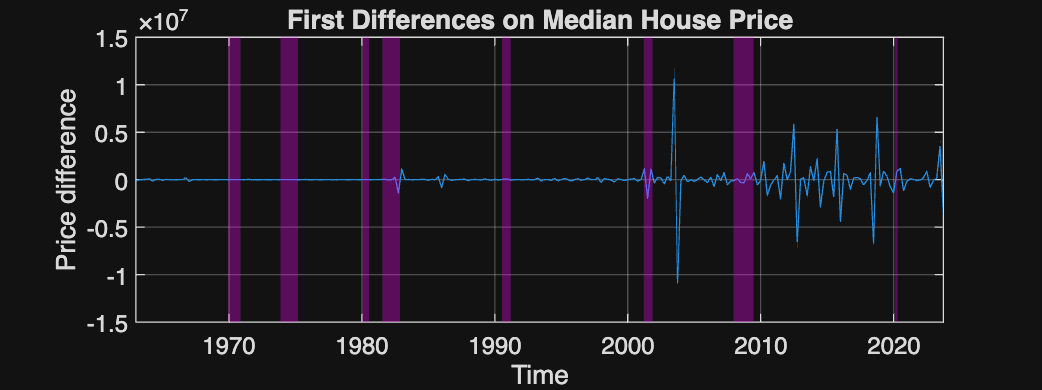

% Calculate the annualized growth rate from the first difference
annual_growth_rate = 100 * (first_difference ./ real_price(1:end-1));

% plot first difference
figure;
plot(data.observation_date(1:end-1), first_difference);
xlabel('Time');
ylabel('Price difference');
title('First Differences on Median House Price');
% plot lines on the major recessions

hBands = recessionplot;
set(hBands,'FaceColor',"magenta",'FaceAlpha',0.3);

grid on;
set(gcf, 'Position', [100, 100, 1600, 600]);

The first difference seems to be bigger and have a bigger deviation as time on.

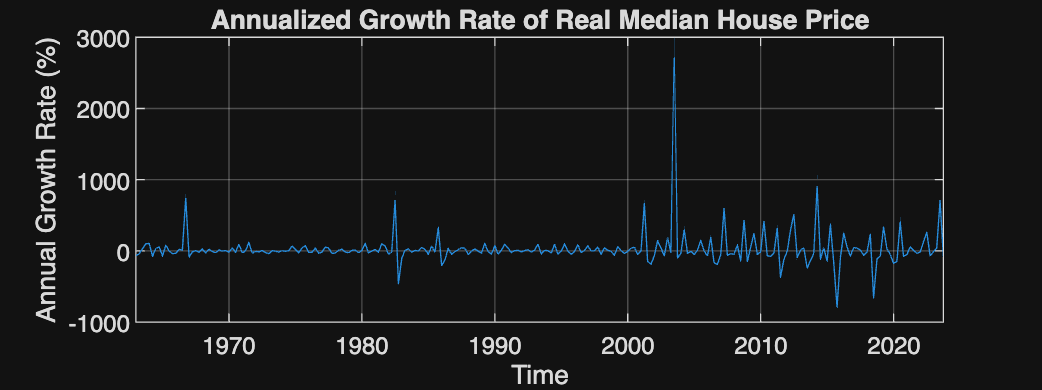

% plot annual_growth_rate
% plot annual growth rate
figure;
plot(data.observation_date(1:end-1), annual_growth_rate);
xlabel('Time');
ylabel('Annual Growth Rate (%)');
title('Annualized Growth Rate of Real Median House Price');
grid on;
set(gcf, 'Position', [100, 100, 1600, 600]);

Slide 5. Plot the sample autocorrelation sample of ∆𝑟𝑔𝑑𝑝𝑝𝑐𝑡 and log(𝑟𝑔𝑑𝑝𝑝𝑐𝑡). Comment in 2 lines			

The correlation between observations at different points in time is strong as shown in the ACF plot showing a series of positive spikes that even at lag 20 remain well outside the 95% confidence bands.  

agr_diff = diff(annual_growth_rate)

agr_diff = 1.0e+03 *

    0.0261
    0.0700
    0.0710
    0.0039
   -0.1797
    0.1124
    0.0192
   -0.1286
    0.1518
   -0.0789
   -0.0416
    0.0081
    0.0528
   -0.0073
    0.7274


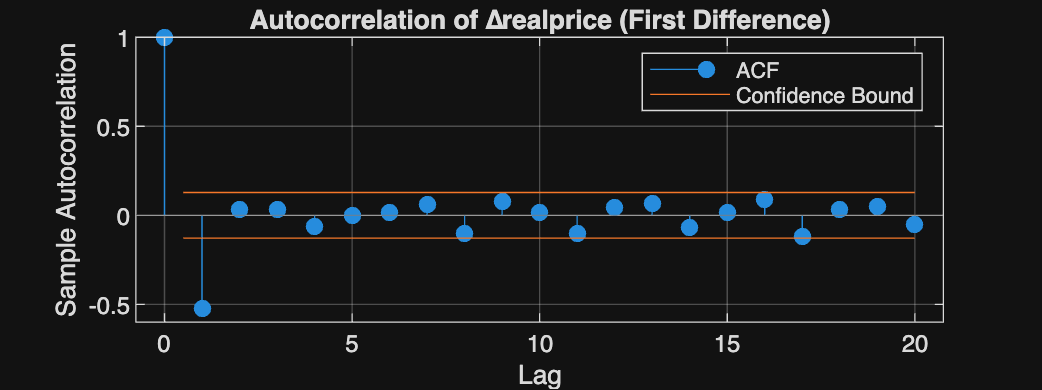

autocorr(first_difference);
title('Autocorrelation of ∆realprice (First Difference)');

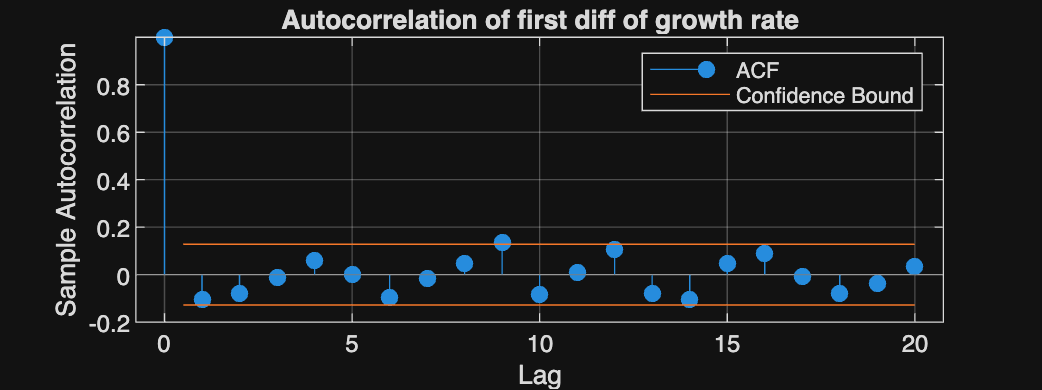

autocorr(annual_growth_rate);
title('Autocorrelation of first diff of growth rate');


autocorr(log(real_price));

Error using autocorr (line 238)
Data must be real and finite.

title('Autocorrelation of Real Price');
num_forecasts = 150
real_price_t = real_price(1:end-num_forecasts);

rwd_model = arima('D',1,'Constant',NaN)
% Fit the ARIMA model to the data
rwd_model_fit = estimate(rwd_model, real_price_t);
% Generate random walk with drift forecasts
[rwwd_forecast, ~] = forecast(rwd_model_fit, num_forecasts, 'Y0', real_price_t);
rwwd = [real_price_t; rwwd_forecast]

s = 48 % quaterly data
srwwd_model = arima('D',0,'Constant',0,'Seasonality',s)
srwwd_model_fit = estimate(srwwd_model, log(real_price_t));
[srwwd_forecast, ~] = forecast(srwwd_model_fit, num_forecasts, 'Y0', log(real_price_t));
rescaled = exp(srwwd_forecast)
srwwd = [real_price_t;rescaled];


figure;

hold on;

plot(data.observation_date, rwwd, '-m');
plot(data.observation_date, srwwd, "-r");
xline(datetime("2013-02-01"), '-r');
plot(data.observation_date, real_price, '-c');

title('Random Walk With Drift Simulation Forecast'); 
ylabel('real price')
% add legend
legend('Random Walk with Drift', 'Seasonal Random Walk', 'Start Of Forecast', 'Real Median House Price', 'Location', 'northwest');
hold off;

set(gcf, 'Position', [100, 100, 1600, 600]);
real = real_price(end-num_forecasts, end)
% calculate mse
% Calculate the mean squared error (MSE)
mse_rwd = mean((real_price(end-num_forecasts+1:end) - rwwd_forecast).^2);
disp(['RWD Mean Squared Error: ', num2str(mse_rwd)]);
mse_srwd = mean((real_price(end - num_forecasts +1:end) - rescaled).^2);
disp(['Seasonal RWD Mean Squared Error: ', num2str(mse_srwd)]);
